clear;close all;clc

Head Plant

% wn = 50; % head natural frequency [rad/s]
% z = 1.2; % head damping ratio []
% I = 0.0895*(10^(-3))^(3); % head inertia about rotation point [kg*m^2]
% k = wn^(2)*I; % head stiffness [N*m/rad]
% cc = 2*sqrt(k*I); % head critical damping [N*m*s/rad]
% c = z*cc; % head damping [N*m*s/rad]

I = 1;
c = 1;
k = 1;

P = tf(1,[I c k])


P =
 
       1
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



P = tf2sym(P);

Visual System

wc = 2*pi*5;
V = tf(wc,[1 wc])


V =
 
    31.42
  ---------
  s + 31.42
 
Continuous-time transfer function.



V = tf2sym(V);

Head Controller

C1 = tf(20,[4 1]);

Wing Controller

C2 = tf(2,[1 1 1]);

Controller Matrix

C = [C1 C2]


C =
 
  From input 1 to output:
    20
  -------
  4 s + 1
 
  From input 2 to output:
       2
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



C = tf2sym(C);

Open-Loop TF

OL = vpa(simplify(expand(V*C*P)),3);
OL = sym2tf(OL)


OL =
 
  From input 1 to output:
                               
                       6.747e11
                               
  ---------------------------------------------------
                                                     
  3.373e10 s^4 + 1.697e11 s^3 + 1.74e11 s^2          
                                                     
                              + 1.403e11 s + 4.295e09
                                                     
 
  From input 2 to output:
                               
                       6.747e10
                               
  ---------------------------------------------------
                                                     
  3.373e10 s^5 + 6.854e10 s^4 + 1.033e11 s^3         
                                                     
               + 7.069e10 s^2 + 3.588e10 s + 1.074e09
                                                     
 
Continuous-time transfer function.



Closed-Loop TF

CL = simplify(expand(V*C*P/(1+V*C(1)*P)));
CL = sym2tf(CL)


CL =
 
  From input 1 to output:
                       628.3
  -----------------------------------------------
  659.7 s^4 + 158.1 s^3 + 162.1 s^2 + 130.7 s + 4
 
  From input 2 to output:
                                   
                    62.83 s + 251.3
                                   
  ---------------------------------------------------
                                                     
  659.7 s^6 + 817.8 s^5 + 979.9 s^4 + 450.8 s^3      
                                                     
                            + 296.7 s^2 + 134.7 s + 4
                                                     
 
Continuous-time transfer function.



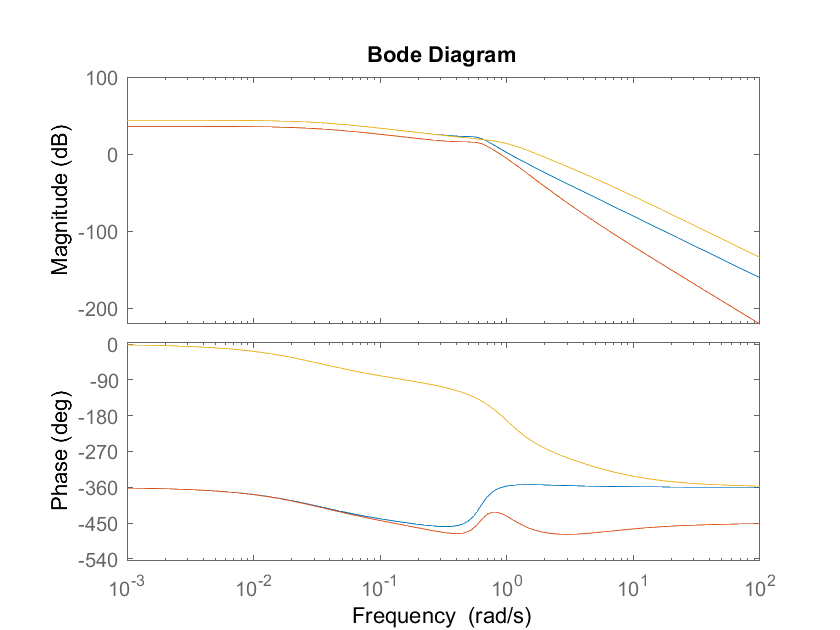


figure (1) ; clf ; hold on
bode(CL(1),CL(2),OL(1))


% for kk = 1:length(CL)   
%     w = 0.5:0.1:20;
%     [mag,phase,wout] = bode(CL(kk),w);
%     plot(wout,mag(:))
%     
% end